## DKE Introduction to Bioinformatics 2022

# **Assignment 5**

*Elena Perego - i6238107*

## Gene Expression

Some toxicology researchers want to know the effect of Cyclosporin A (CSA) on human cells. They take two doses of this compound (20uM and 3uM) and take samples after 12, 24, 48 and 72 hours of exposure. They also take samples from cells exposed to just the solvent which the CSA is normally dissolved into, DMSO (eg the samples labelled DMSO are untreated and the samples labelled CSA are treated). They want to know which genes are affected by the CSA.  

After preprocessing (as above) pick at least one dose/timepoint combination and find the differentially expressed genes.

## Experiment 1

In this experiment I want to study the genes affected by CSA by comparing the untreated samples DMSO after 12 hours with the treated samples with CSA 20uM doses after 12 hours as well

Here, I get the data, I perform a log2 transform, and I remove the unneccesary columns.

experiment = readtable("Bio Informatics\raw_data_labelled.csv");
data = log2(table2array(experiment(1:height(experiment),2:width(experiment))));

Then, I create a boxplot of the daa to understand if normalization is needed.

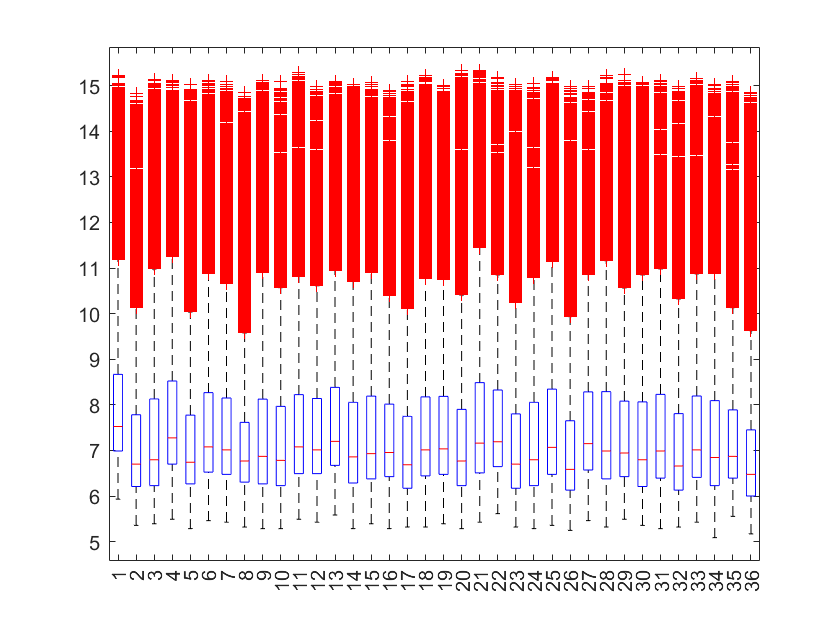

boxplot(data);

It is needed since the boxes where most data lies, between the 1st and the 3rd quartiles, differe from each sample.

Therefore, the data is normalized using a quantile normalization taking the median of the ranked values instead of the mean to avoid outlier's impact. The boxplot is visualized to ensure the difference with the previous one.

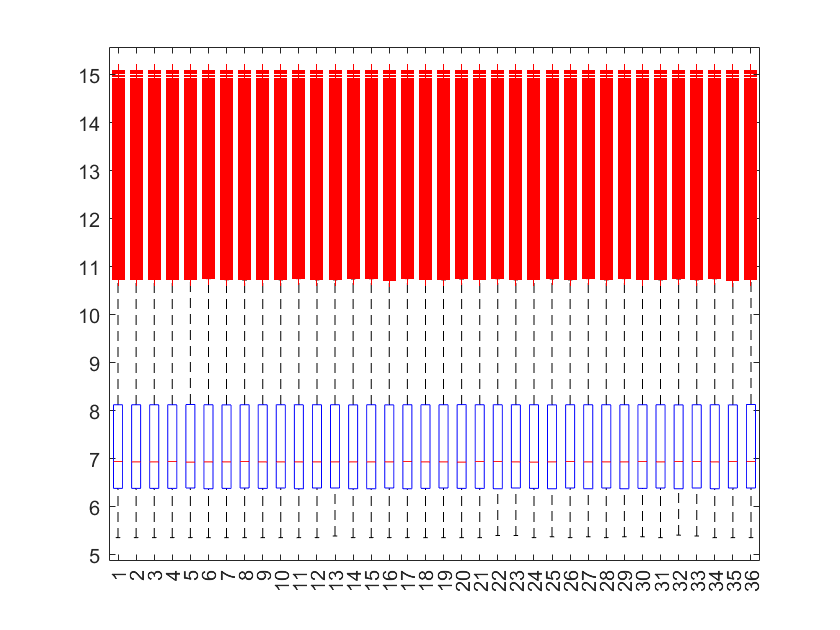

data_norm = quantilenorm(data, 'Median', true);
boxplot(data_norm);

Now, to find the correct cut-off over which genes can be defined as over-expressed, an histogram of all the values is plotted. Over-expressed genes are the most relevant to look at to understand the effect of CSA since they are the ones that were more expressed in the samples.

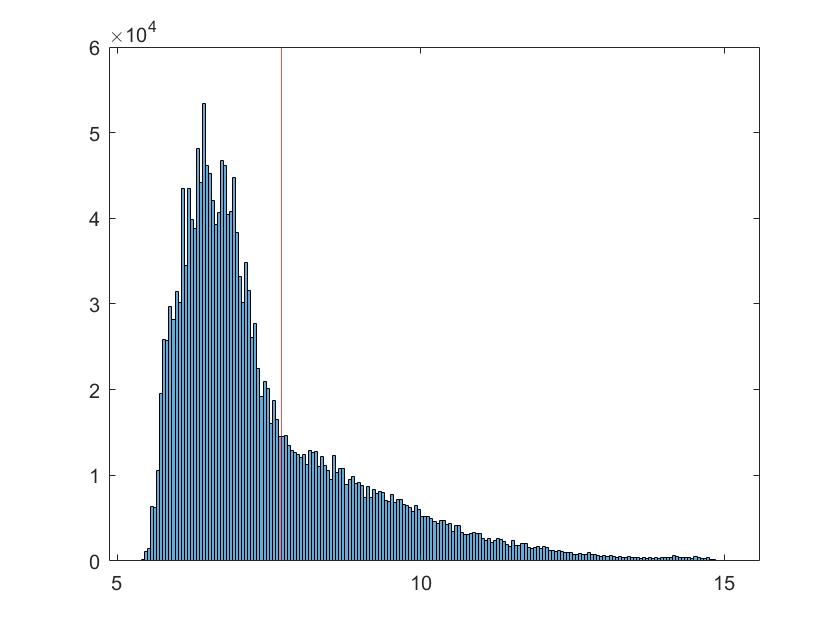

histogram(data_norm)
xline(7.7, 'Color', 'Red')

This plot represents two distributions combine, one gaussian which represents the unexpressed genes giving a backrgound noise signal, and the other logarithmic which represents the expressed genes giving the real signal. Since the gaussian distribution is more visible, the cut off has been decided based on its simmetry. Considering that the distribution approximately starts at 5.7 and the peak is at approximately at 6.7, then the end is approxiamtely at 7.7. 

Before accessing the over-expressed genes, the data of study filtered for untreated samples DMSO after 12 hours and treated samples with CSA 20uM doses after 12 hours is stored in a separate table and a vector of labels is created to easily filter this new table.

data_study = [data_norm(:,2) data_norm(:,14) data_norm(:,26) data_norm(:,3) data_norm(:,15) data_norm(:,27)];
treatment = ["DMSO", "DMSO", "DMSO", "CSA", "CSA", "CSA"];

Now, the over-expressed genes are counted and their indeces are stored for later access. A gene is considered over-expressed if its value is higher than the cutoff for all three samples of at least one group, either untreated or treated.

count = 0;
cut_off = 7.7;
expressed_genes_index = int16.empty(16768,0);
for i=1:height(data_study)
    if all(data_study(i,treatment=="DMSO") >= cut_off) || all(data_study(i,treatment=="CSA") >= cut_off)
        count = count+1;
        expressed_genes_index{count} = i;
    end
end
count

count = 16768

16768 is the resulted count of over-expressed genes.

Now, among the over-expresssed genes, the ones that are really effected by the CSA treatment are the ones with a high or low fold change and statistically significant.

The log2 fold change, which represents the difference in expression between the over-expressed genes of the two groups,  is calculated as


$$\textrm{log2}\;\textrm{fold}\;\textrm{change}=\textrm{average}\left({{\textrm{expressed}}_{\textrm{genes}} }_{\textrm{CSA}} -{{\textrm{expressed}}_{\textrm{genes}} }_{\textrm{DMSO}} \right)$$


expressed_genes = data_study(cell2mat(expressed_genes_index),:);
fold_change = double.empty(0,height(expressed_genes));
for i=1:height(expressed_genes)
    fold_change{i} = mean(expressed_genes(i,treatment=="CSA"))-mean(expressed_genes(i,treatment=="DMSO"));
end
fold_change = cell2mat(fold_change);

Then, to check the statistical significance, a two-tail t-test is performed on the two groups of over-expressed genes with the multiple testing correction Benjamini-Hochberg.

[h, p] = ttest2(expressed_genes(:,treatment=="DMSO")', expressed_genes(:,treatment=="CSA")')

h =      0     1     1     1     0     0     0     1     1     0     0     0     1     0     1     0     0     0     0     0     1     1     1     0     0     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0


p =     0.6322    0.0015    0.0073    0.0023    0.2165    0.3546    0.5025    0.0192    0.0103    0.0629    0.8691    0.0948    0.0002    0.2951    0.0041    0.1117    0.0918    0.2287    0.8487    0.0824    0.0040    0.0307    0.0258    0.0757    0.8874    0.6902    0.0001    0.1567    0.0006    0.4395    0.2827    0.8753    0.6317    0.1809    0.0468    0.6706    0.9516    0.7489    0.0962    0.0704    0.0897    0.4426    0.0816    0.5608    0.0593    0.0804    0.0017    0.8596    0.0072    0.8509


adjusted_p = mafdr(p, 'BHFDR', true)

adjusted_p =     0.7145    0.0154    0.0326    0.0180    0.3170    0.4613    0.6016    0.0575    0.0395    0.1280    0.9060    0.1714    0.0084    0.4001    0.0240    0.1934    0.1674    0.3298    0.8905    0.1547    0.0238    0.0786    0.0699    0.1461    0.9195    0.7633    0.0061    0.2484    0.0110    0.5437    0.3875    0.9105    0.7143    0.2767    0.1040    0.7473    0.9672    0.8117    0.1732    0.1387    0.1646    0.5463    0.1537    0.6531    0.1226    0.1521    0.0162    0.8982    0.0324    0.8922


Now, upregulated and downregulated genes, which are the ones that greatly and significantly increased expression due to CSA treatment or decreased, respectively, are accessed and counted.

upregulated = 0;
upregulated_genes = char.empty(0,459);
downregulated = 0;
downregulated_genes = char.empty(0,372);
for i=1:height(expressed_genes)
    if adjusted_p(i)<0.05
        if  fold_change(i)>1
            upregulated = upregulated+1;
            upregulated_genes{upregulated} = experiment{expressed_genes_index{i},"Var1"};
        end
        if  fold_change(i)<-1
                downregulated = downregulated+1;
                downregulated_genes{downregulated} = experiment{expressed_genes_index{i},"Var1"};
        end
    end
end
upregulated

upregulated = 459

downregulated

downregulated = 372

cell2table(upregulated_genes)

ans = 1×459 table
    upregulated_genes1    upregulated_genes2    upregulated_genes3    upregulated_genes4    upregulated_genes5    upregulated_genes6    upregulated_genes7    upregulated_genes8    upregulated_genes9    upregulated_genes10    upregulated_genes11    upregulated_genes12    upregulated_genes13    upregulated_genes14    upregulated_genes15    upregulated_genes16    upregulated_genes17    upregulated_genes18    upregulated_genes19    upregulated_genes20    upregulated_genes21    upregulated_genes22    upregulated_genes23    upregulated_genes24    upregulated_genes25

cell2table(downregulated_genes)

ans = 1×372 table
    downregulated_genes1    downregulated_genes2    downregulated_genes3    downregulated_genes4    downregulated_genes5    downregulated_genes6    downregulated_genes7    downregulated_genes8    downregulated_genes9    downregulated_genes10    downregulated_genes11    downregulated_genes12    downregulated_genes13    downregulated_genes14    downregulated_genes15    downregulated_genes16    downregulated_genes17    downregulated_genes18    downregulated_genes19    downregulated_genes20    downregulated_genes21    downregulated_genes22    downregulated_genes23    downregulated

Finally, the names of all the upregulated and downregulated genes are shown to further study for biologists. 

## Experiment 2

In this experiment I want to study the genes affected by CSA by comparing the untreated samples DMSO after 48 hours with the treated samples with CSA 20uM doses after 48 hours as well. The only change in the code is the data of study.

data_study = [data_norm(:,8) data_norm(:,20) data_norm(:,32) data_norm(:,9) data_norm(:,21) data_norm(:,33)];
treatment = ["DMSO", "DMSO", "DMSO", "CSA", "CSA", "CSA"];
% Find expressed genes
count = 0;
cut_off = 7.7;
expressed_genes_index = int16.empty(17228,0);
for i=1:height(data_study)
    if all(data_study(i,treatment=="DMSO") >= cut_off) || all(data_study(i,treatment=="CSA") >= cut_off)
        count = count+1;
        expressed_genes_index{count} = i;
    end
end
count

count = 17228

% Calculate fold change
expressed_genes = data_study(cell2mat(expressed_genes_index),:);
fold_change = double.empty(0,height(expressed_genes));
for i=1:height(expressed_genes)
    fold_change{i} = mean(expressed_genes(i,treatment=="CSA"))-mean(expressed_genes(i,treatment=="DMSO"));
end
fold_change = cell2mat(fold_change);
% Find adjusted p-values for statistical significance
[h, p] = ttest2(expressed_genes(:,treatment=="DMSO")', expressed_genes(:,treatment=="CSA")')

h =      1     0     1     1     1     1     0     0     0     0     1     1     0     0     0     1     1     1     1     0     1     0     1     1     1     0     0     1     1     0     1     1     1     0     0     1     0     0     1     0     0     0     0     1     0     0     0     0     0     0


p =     0.0178    0.1518    0.0004    0.0335    0.0116    0.0057    0.8284    0.1209    0.2316    0.2490    0.0001    0.0020    0.4794    0.1503    0.7217    0.0018    0.0030    0.0458    0.0080    0.0645    0.0056    0.9029    0.0290    0.0007    0.0017    0.5804    0.5626    0.0048    0.0002    0.4877    0.0038    0.0040    0.0219    0.0690    0.8224    0.0005    0.0860    0.4610    0.0003    0.4178    0.1974    0.5977    0.2300    0.0180    0.9596    0.3504    0.5359    0.1627    0.0696    0.2809


adjusted_p = mafdr(p, 'BHFDR', true)

adjusted_p =     0.0392    0.2122    0.0046    0.0634    0.0291    0.0180    0.8630    0.1754    0.3010    0.3193    0.0029    0.0096    0.5512    0.2105    0.7717    0.0090    0.0123    0.0812    0.0224    0.1060    0.0179    0.9236    0.0570    0.0057    0.0089    0.6460    0.6294    0.0162    0.0036    0.5592    0.0141    0.0145    0.0460    0.1118    0.8583    0.0050    0.1331    0.5335    0.0040    0.4926    0.2637    0.6614    0.2994    0.0395    0.9694    0.4251    0.6050    0.2247    0.1124    0.3534


% Find and count upregulated and downregulated genes
upregulated = 0;
upregulated_genes = char.empty(0,1579);
downregulated = 0;
downregulated_genes = char.empty(0,1198);
for i=1:height(expressed_genes)
    if adjusted_p(i)<0.05
        if  fold_change(i)>1
            upregulated = upregulated+1;
            upregulated_genes{upregulated} = experiment{expressed_genes_index{i},"Var1"};
        end
        if  fold_change(i)<-1
                downregulated = downregulated+1;
                downregulated_genes{downregulated} = experiment{expressed_genes_index{i},"Var1"};
        end
    end
end
upregulated

upregulated = 1579

downregulated

downregulated = 1198

cell2table(upregulated_genes)

ans = 1×1579 table
    upregulated_genes1    upregulated_genes2    upregulated_genes3    upregulated_genes4    upregulated_genes5    upregulated_genes6    upregulated_genes7    upregulated_genes8    upregulated_genes9    upregulated_genes10    upregulated_genes11    upregulated_genes12    upregulated_genes13    upregulated_genes14    upregulated_genes15    upregulated_genes16    upregulated_genes17    upregulated_genes18    upregulated_genes19    upregulated_genes20    upregulated_genes21    upregulated_genes22    upregulated_genes23    upregulated_genes24    upregulated_genes2

cell2table(downregulated_genes)

ans = 1×1198 table
    downregulated_genes1    downregulated_genes2    downregulated_genes3    downregulated_genes4    downregulated_genes5    downregulated_genes6    downregulated_genes7    downregulated_genes8    downregulated_genes9    downregulated_genes10    downregulated_genes11    downregulated_genes12    downregulated_genes13    downregulated_genes14    downregulated_genes15    downregulated_genes16    downregulated_genes17    downregulated_genes18    downregulated_genes19    downregulated_genes20    downregulated_genes21    downregulated_genes22    downregulated_genes23    downregulate

## Experiment 3

In this experiment I want to study the genes affected by CSA by comparing the untreated samples DMSO after 12 hours with the treated samples with CSA 3uM doses after 12 hours as well. The only change in the code is the data of study.

data_study = [data_norm(:,2) data_norm(:,14) data_norm(:,26) data_norm(:,4) data_norm(:,16) data_norm(:,28)];
treatment = ["DMSO", "DMSO", "DMSO", "CSA", "CSA", "CSA"];
% Find expressed genes
count = 0;
cut_off = 7.7;
expressed_genes_index = int16.empty(16715,0);
for i=1:height(data_study)
    if all(data_study(i,treatment=="DMSO") >= cut_off) || all(data_study(i,treatment=="CSA") >= cut_off)
        count = count+1;
        expressed_genes_index{count} = i;
    end
end
count

count = 16715

% Calculate fold change
expressed_genes = data_study(cell2mat(expressed_genes_index),:);
fold_change = double.empty(0,height(expressed_genes));
for i=1:height(expressed_genes)
    fold_change{i} = mean(expressed_genes(i,treatment=="CSA"))-mean(expressed_genes(i,treatment=="DMSO"));
end
fold_change = cell2mat(fold_change);
% Find adjusted p-values for statistical significance
[h, p] = ttest2(expressed_genes(:,treatment=="DMSO")', expressed_genes(:,treatment=="CSA")')

h =      0     1     1     1     0     0     0     1     1     0     0     1     1     0     1     1     1     0     0     0     0     0     1     0     0     0     0     0     1     0     1     0     1     0     0     0     0     0     0     1     1     0     0     0     0     1     0     1     0     1


p =     0.4624    0.0031    0.0051    0.0279    0.1251    0.6489    0.5567    0.0099    0.0039    0.1915    0.3722    0.0049    0.0034    0.8146    0.0053    0.0037    0.0059    0.2044    0.0969    0.2765    0.1150    0.1756    0.0035    0.7701    0.0533    0.2887    0.6207    0.5127    0.0011    0.1362    0.0003    0.1698    0.0429    0.1210    0.3110    0.1195    0.8408    0.8970    0.3966    0.0079    0.0222    0.0627    0.2990    0.2890    0.5909    0.0299    0.2202    0.0078    0.8084    0.0050


adjusted_p = mafdr(p, 'BHFDR', true)

adjusted_p =     0.5709    0.0196    0.0253    0.0739    0.2151    0.7316    0.6542    0.0375    0.0221    0.2951    0.4846    0.0248    0.0205    0.8649    0.0259    0.0213    0.0277    0.3095    0.1789    0.3874    0.2023    0.2777    0.0208    0.8306    0.1160    0.4003    0.7084    0.6156    0.0118    0.2293    0.0074    0.2706    0.0991    0.2098    0.4230    0.2080    0.8850    0.9271    0.5082    0.0329    0.0634    0.1300    0.4106    0.4006    0.6838    0.0776    0.3267    0.0326    0.8602    0.0252


% Find and count upregulated and downregulated genes
upregulated = 0;
upregulated_genes = char.empty(0,594);
downregulated = 0;
downregulated_genes = char.empty(0,454);
for i=1:height(expressed_genes)
    if adjusted_p(i)<0.05
        if  fold_change(i)>1
            upregulated = upregulated+1;
            upregulated_genes{upregulated} = experiment{expressed_genes_index{i},"Var1"};
        end
        if  fold_change(i)<-1
                downregulated = downregulated+1;
                downregulated_genes{downregulated} = experiment{expressed_genes_index{i},"Var1"};
        end
    end
end
upregulated

upregulated = 594

downregulated

downregulated = 454

cell2table(upregulated_genes)

ans = 1×594 table
    upregulated_genes1    upregulated_genes2    upregulated_genes3    upregulated_genes4    upregulated_genes5    upregulated_genes6    upregulated_genes7    upregulated_genes8    upregulated_genes9    upregulated_genes10    upregulated_genes11    upregulated_genes12    upregulated_genes13    upregulated_genes14    upregulated_genes15    upregulated_genes16    upregulated_genes17    upregulated_genes18    upregulated_genes19    upregulated_genes20    upregulated_genes21    upregulated_genes22    upregulated_genes23    upregulated_genes24    upregulated_genes25

cell2table(downregulated_genes)

ans = 1×454 table
    downregulated_genes1    downregulated_genes2    downregulated_genes3    downregulated_genes4    downregulated_genes5    downregulated_genes6    downregulated_genes7    downregulated_genes8    downregulated_genes9    downregulated_genes10    downregulated_genes11    downregulated_genes12    downregulated_genes13    downregulated_genes14    downregulated_genes15    downregulated_genes16    downregulated_genes17    downregulated_genes18    downregulated_genes19    downregulated_genes20    downregulated_genes21    downregulated_genes22    downregulated_genes23    downregulated

## Conclusion

The goal of the study was to know the genes affected by CSA treatment. Three scenario have been analyzed

- comparing the untreated samples DMSO **after 12** hours with the treated samples with CSA **20uM** doses **after 12 hours**

- comparing the untreated samples DMSO **after 48** hours with the treated samples with CSA **20uM** doses **after 48 hours**

- comparing the untreated samples DMSO **after 12 hours** with the treated samples with CSA **3uM** doses **after 12 hours**

Analyzing together the results of these experiments lead to two main conlclusion:

- CSA treatment has a stronger effect on the genes later in time. Comparing experiment 1 and 2, there is an important increase in both upregulated and downregulated from 459 to1579, and from 372 to 1198, respectively. However, the ratio of upregulated and downregulated remains constant of 1.3.

- Increase in CSA treatment dosage leads to a substantial increase in downregulated genes. Comparing experiment 1 and 3, there is an important increase in only downregulated, from 372 to 594, and a very small decrease in upregulated, from 459 to 454, respectively. This means that the treatment consists in lower expressed genes whose expression harms the cell.